This repository uses MPM as a package manager to manage dependencies.  You must always start your files with the following line to add these dependencies to the local path

mpm addpath % set local path to include dependencies

mpm: Adding cxro-intern-imaging-utils to MATLAB path


Create a rectangle

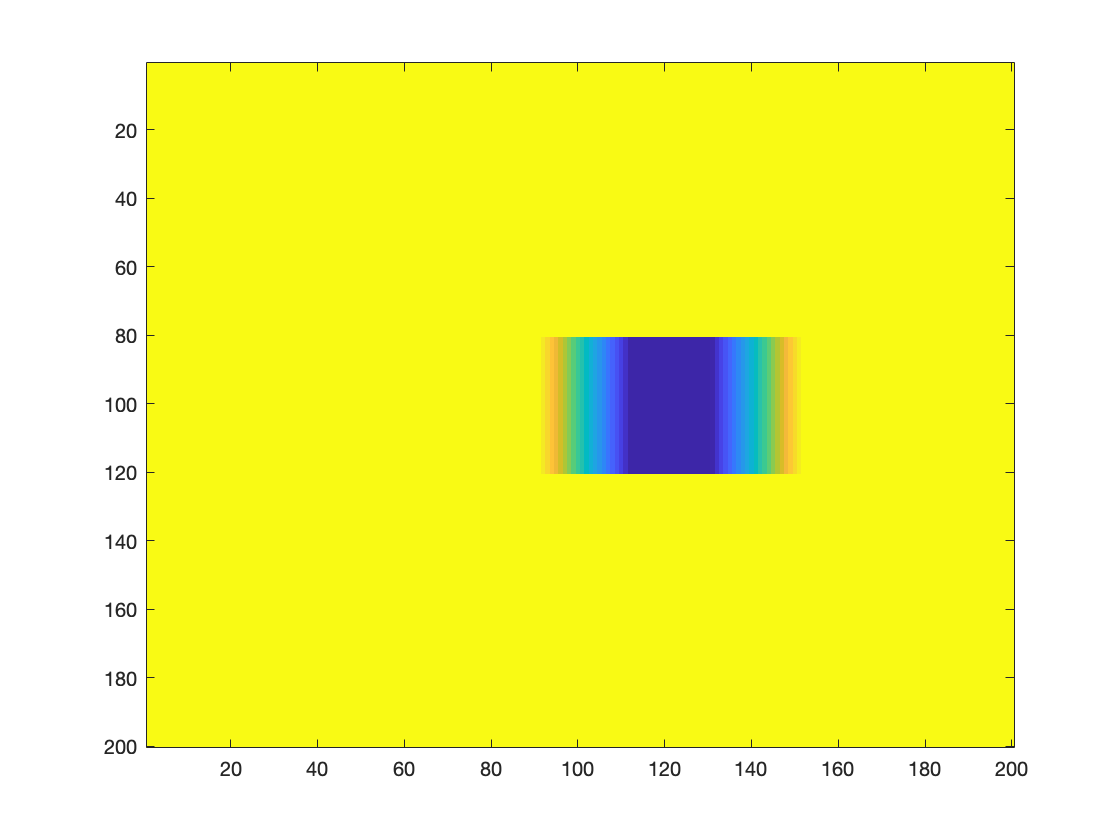

xIdx = linspace(0, 100, 200);
yIdx = linspace(0, 100, 200);

[X, Y] = meshgrid(xIdx, yIdx);

[wave, idealMask] = createRectangleTransmission(X, Y, [50, 50], 50, [20, 20, 100], 'Mo');

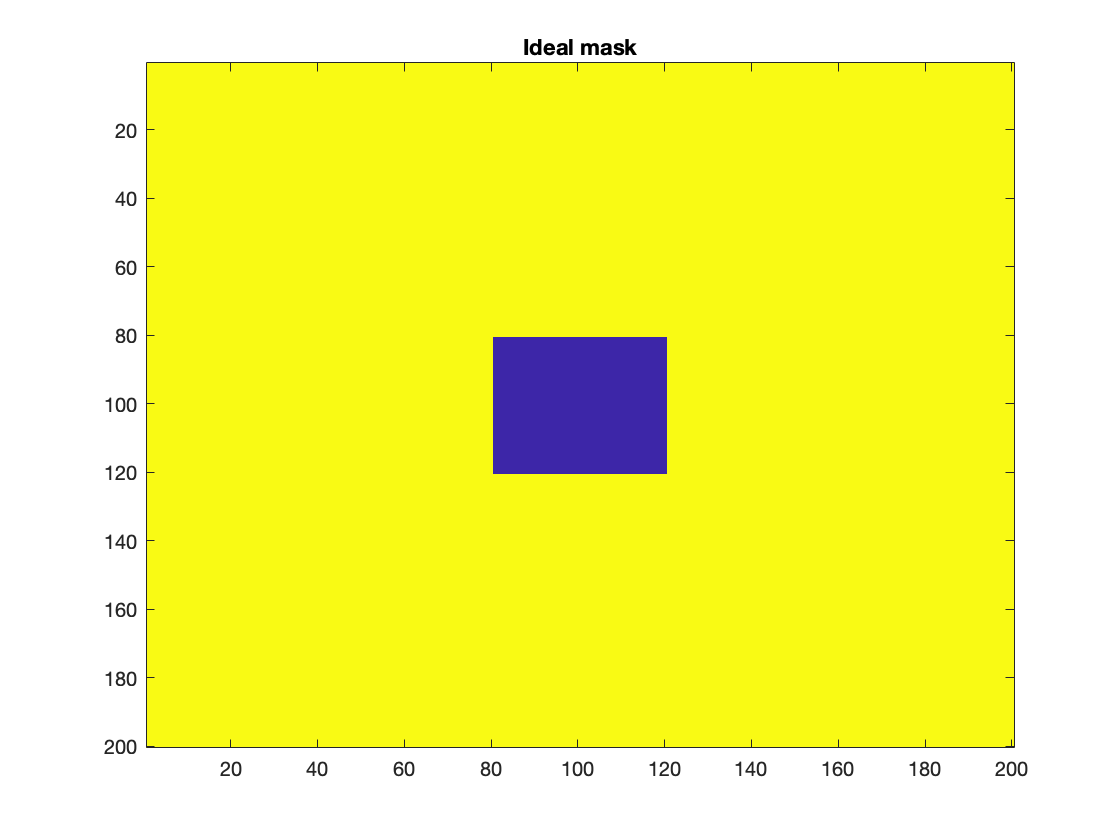


%% Image ideal mask
imagesc(idealMask)
title('Ideal mask')

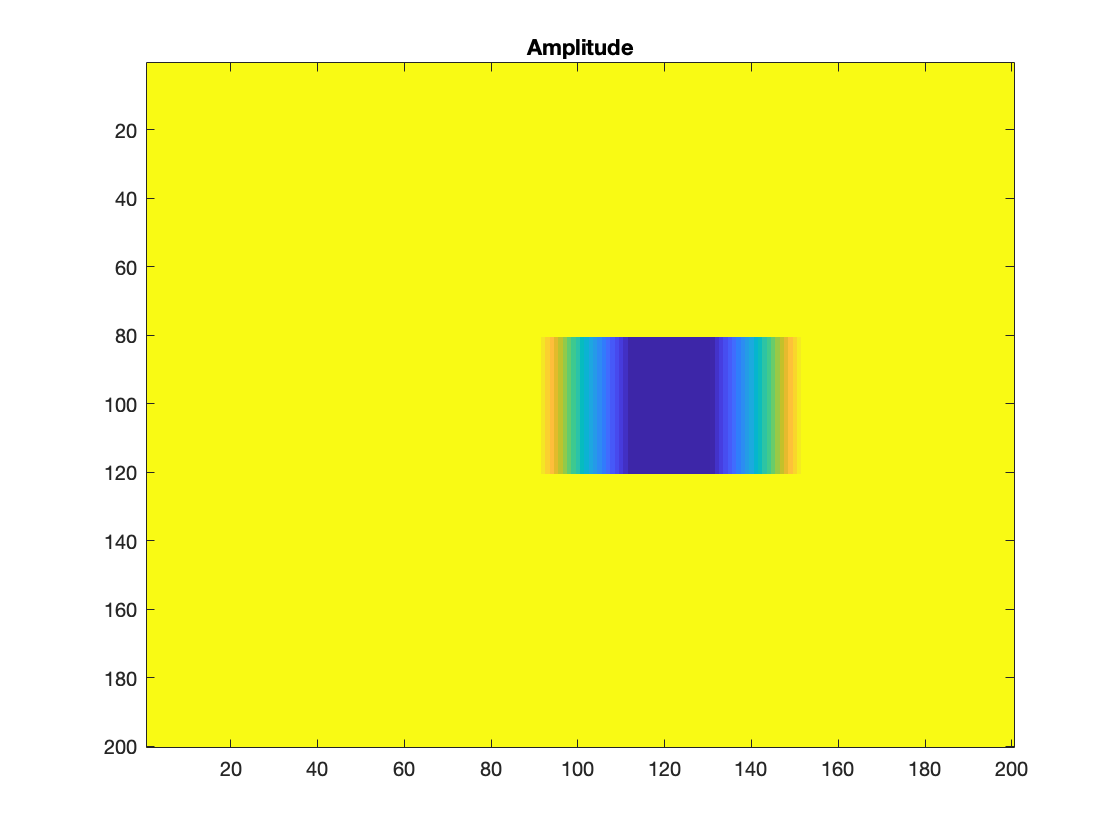


%% Image amplitude
imagesc(abs(wave));
title('Amplitude')

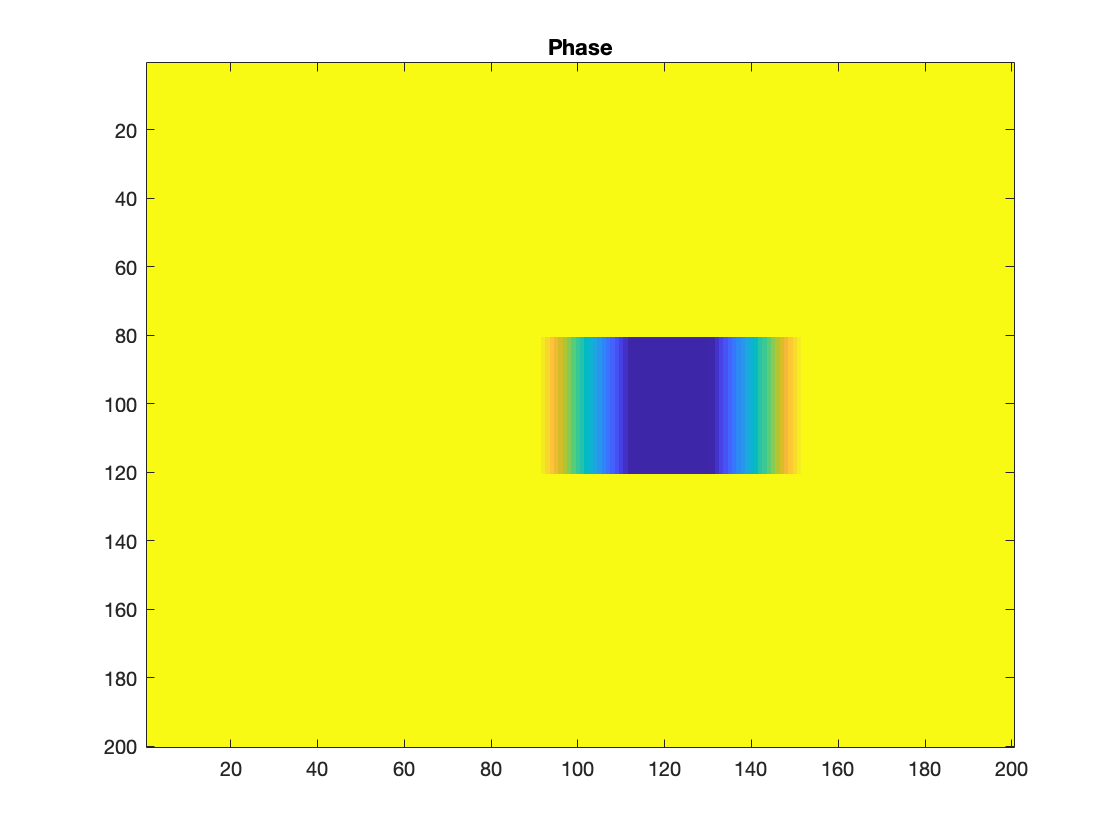


%% Image phase:
imagesc(angle(wave));
title('Phase')